## Lernziele

- Anwendung des Intnrinsic Rolling auf einen Speicher

- Umsetzung der Algorithmik

- Sensitivitätsbetrachtung

**Anmerkung: **

Für eine bessere Nachvollziehbarkeit und  Performance der Berechnung wird die Optimierung und Bewirtschaftung nur tageweise durchgeführt!

Hierzu muss als zusätzliche Restriktion gelten:  **Anfangsfüllstand = Endfüllstand** (andernfalls würde der Speicher immer nur den minimalen Füllstand am Tagesende anstreben)

In Realität würde die Optimierung deutlich weiter in die Zukunft reichen, um die Auswirkungen der Endfüllstandsbedingung auf die optimale Entscheidung am Day-Ahead zu relaxieren. 

Der Erlös in der Zukunft würde in das Kalkühl der Intrinsic Rolling-Entscheidung integriert werden (siehe die Vorlesungsfolien hierzu)

Der Füllstand würde sich dynamisch im Zeitablauf entwicklen und von Tag zu Tag weitergereicht.

**Vorbereitung**

clear;clc;close all;warning off
options = optimoptions('intlinprog','MaxTIME',100,'Display','none');
for i=1:4 gr.f(i)=figure('Color', 'w','windowstyle','docked','PaperPosition',[.1 .1 16 6],'visible','on');end

**Parameter der Simulation**

STOR.daydt = 96;                                                        % Anzahl der Stunden/Produkte Handelsmarkt

Hinweis: mit dem Parameter days können Sie die Anzahl der zu betrachtenden Handelstage auswählen

days=40;                                        % Anzahl der zu simulierenden Handelstage 

weitere abgeleitete Hilfsgrößen

dtAnf =1:STOR.daydt:(days)*STOR.daydt;                                  % Zeitstempel (Stunde) Beginn des jeweiligen Handelstages 
dtEnd =STOR.daydt:STOR.daydt:(days)*STOR.daydt;                         % Zeitstempel (Stunde) Ende des jeweiligen Handelstages 
STOR.nHours1=1:STOR.daydt-1;                                            % Zeitindex beginnend mit Stunde 1 bis T-1    
STOR.nHours2=2:STOR.daydt;                                              % Zeitindex beginnend mit Stunde 2 bis T              
STOR.nHours3=1:STOR.daydt;                                              % Zeitindex beginnend mit Stunde 1 bis T

**Einladen der Preise**

load Price.mat                                                % Einladen der Preise auf den einzelnen Marktstufen                        

## Laden der Speichercharakteristika

STOR.aggr =readtable('Speicherdaten.xlsx');  

## Parametrierung des Speichers

Speicher

STOR.levelMax_el = STOR.aggr{7,3};                                         % Kapazität in MWh Netto
STOR.levelAnf_el=0.5 *STOR.levelMax_el;                                    % 50% Anfangsfüllstand [MWh]

Turbine/Pumpe

STOR.Turbmax_el = STOR.aggr{1,3}/4;                                        % Turbinierkapazität Netto [MWh/(1/4h)]
STOR.Turbmin_el = STOR.aggr{2,3}/4;                                        % Turbinierkapazität Netto [MWh/(1/4h)]
STOR.Pumpmax_el = STOR.aggr{3,3}/4;                                        % Pumpkapazität Netto [MWh/(1/4)h]
STOR.Pumpmin_el = STOR.aggr{4,3}/4;                                        % Pumpkapazität Netto [MWh/(1/4)h]
STOR.Pumpeta =STOR.aggr{6,3};                                              % Pumpwirkungsgrad =Walzwirkungsgrad               

## klass. Optimierung lineare Einsatzoptimierung

**Definition der Variablen**

% amount of Mel turbined or pumped by plant
vTurb_el = optimvar('Turb_el',STOR.daydt,1,'LowerBound',0,'UpperBound',STOR.Turbmax_el);  % Leistung in MWh/h
vPump_el = optimvar('Pump_el',STOR.daydt,1,'LowerBound',0,'UpperBound',STOR.Pumpmax_el);  % Leistung in MWh/h (Brutto)
% indicator if Turbine is on
vTurbOn = optimvar('TurbOn',STOR.daydt,1,'Type','integer','LowerBound',0,'UpperBound',1);
% indicator if Pump is on
vPumpOn = optimvar('PumpOn',STOR.daydt,1,'Type','integer','LowerBound',0,'UpperBound',1);
% Level
vLevel_el = optimvar('Level_el',STOR.daydt,1,'LowerBound',0,'UpperBound',STOR.levelMax_el);

**Zielfunktion**

prob = optimproblem;
prob.ObjectiveSense='maximize';

**Restriktionen Max und Min-Fahrweise für Turbine und Pumpe**

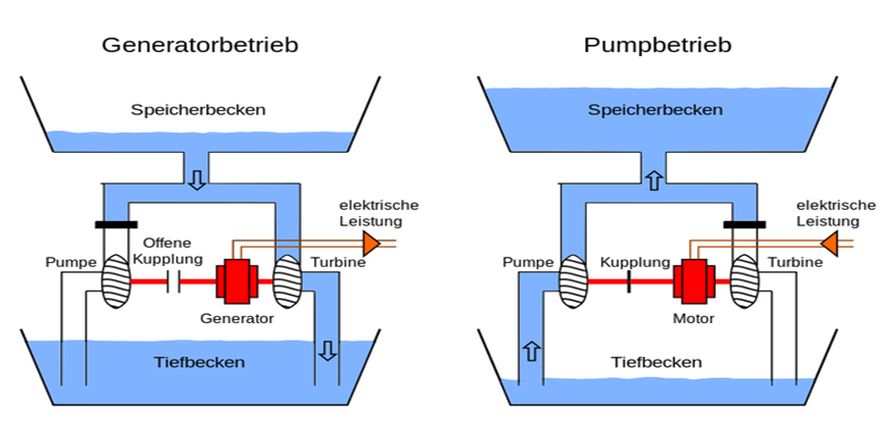

prob.Constraints.TurbPump = vTurbOn+vPumpOn<=1; 
prob.Constraints.MaxTurb_elWhenTurb = vTurb_el <= STOR.Turbmax_el.*vTurbOn; 
prob.Constraints.MaxTurb_elWhenPump = vPump_el <= STOR.Pumpmax_el.*vPumpOn;
prob.Constraints.MinTurb_elWhenTurb = vTurb_el >= STOR.Turbmin_el.*vTurbOn; 
prob.Constraints.MinTurb_elWhenPump = vPump_el >= STOR.Pumpmin_el.*vPumpOn;

**Restriktion, dass immer eine Viertelstunde umgerüstet werden muss**

prob.Constraints.ruest1 = vPumpOn(STOR.nHours1,1) +vTurbOn(STOR.nHours2,1) <= 1;
prob.Constraints.ruest2 = vTurbOn(STOR.nHours1,1) +vPumpOn(STOR.nHours2,1) <= 1;

**Restriktion zum Füllstand**

prob.Constraints.Level = optimconstr(STOR.daydt,1);                                                          % Initialisierung
prob.Constraints.Level(STOR.nHours2) = vLevel_el(STOR.nHours2)==...                                          % Füllstand in t
                                   vLevel_el(STOR.nHours1)+...                                               % Füllstand in t-1
                                   vPump_el(STOR.nHours1).*STOR.Pumpeta-...                                  % Netto-Pumpleistung in t
                                   vTurb_el(STOR.nHours1);                                                   % Netto-Turbinierleistung in t
prob.Constraints.level_anf = vLevel_el(1) == STOR.levelAnf_el;                                               % im ersten Zeitschritt muss Anfangsfüllstand erreicht werden
prob.Constraints.level_end = vLevel_el(STOR.daydt) == STOR.levelAnf_el;                                      % im letzten Zeitschritt muss Anfangsfüllstand erreicht werden

## intrinsic Rolling

tic
% Anzahl der Handelstage
for day=1:days
    t=dtAnf(day);               % Beginn Betrachtungszeitraum Einsatzoptimierung (rollierend)
    T=dtEnd(day);               % Ende Betrachtungszeitraum Einsatzoptimierung (rollierend)

### Optimierung der 1.ten Marktstufe

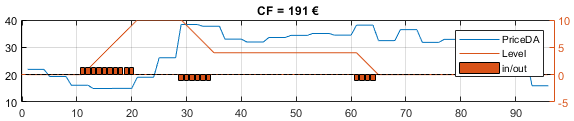

    prob.Objective =  sum((vTurb_el- vPump_el).*Price.AP1zr(t:T));      % Erlös [€]
    [OPT1.sol{day},OPT1.Cashflow(day,1),OPT1.exitflag(day,1),OPT1.output(day,1)] = solve(prob,[],'options',options);
    
    % Preis
    Market1.preis(day,:)=Price.AP1zr(t:T);

    % optimale Position DA (ohne Vorbelegung) (Verkauf negativ; Kauf positiv)
    Market1.action(day,:)=OPT1.sol{day}.Pump_el - OPT1.sol{day}.Turb_el;
    
    % Umrechnung der Viertelstunden in Stundenblöcke,
    for i=1:24  Market1.action(day,(i-1)*4+1:i*4)=mean(Market1.action(day,(i-1)*4+1:i*4));end
    
    Market1.level(day,:) = OPT1.sol{day}.Level_el;

    % Wert optimale Position DA (ohne Vorbelegung)
    Market1.CFday(day,1)= -Market1.action(day,:)*Price.AP1zr(t:T);
        
    % Handelsgeschäfte DA (gleich optimaler Position)
    Market1.VolumeTrade(day,:) = Market1.action(day,:);
    
    % Buchwert der Handelsgeschäfte (gleich optimaler Position)
    Market1.ValueTrade(day,:) = Market1.CFday(day,1);
       

### **  Optimierung der 2.ten Marktstufe**

Einsatzoptimierung ("unvorbelegt") unter aktualisierter Preisstellung der Lieferperiode

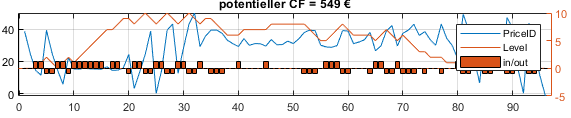

        % Einsatzoptimierung
        prob.Objective =  sum((vTurb_el- vPump_el).*Price.AP2zr(t:T));      % Erlös [€]
        [OPT2.sol{day},OPT2.Cashflow(day,1),OPT2.exitflag(day,1),OPT2.output(day,1)] = solve(prob,[],'options',options);
        
        % Preis
        Market2.preis(day,:)=Price.AP2zr(t:T);

        % optimale Position ID (ohne Vorbelegung)
        Market2.action(day,:)=OPT2.sol{day}.Pump_el - OPT2.sol{day}.Turb_el;
       
        Market2.level(day,:) = OPT2.sol{day}.Level_el;
        
        % Wert optimale Position ID (ohne Vorbelegung)
        Market2.CFday(day,1)= -Market2.action(day,:)*Price.AP2zr(t:T);          

**  Entscheidung zum Rollieren der Position **

- Bestimmung der Anpassungs-Handelsgeschäfte (VolumeTrade) zur Absicherung des neuen Optimums

- Bestimmung des Buchwertes (Preis*Menge) der Anpassungs-Handelsgeschäfte (ValueTrade)

- Bestimmung der Differenz des "Restwertes" zwischen altem und neuem Optimums

- Durchführung Rollieren, falls gilt: $\textrm{Mahg}+\textrm{diff}\left(\textrm{Restwert}\right)>0$

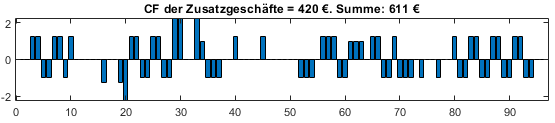

        % Bestimmung der Handelsgeschäfte, um in neue Position zu rollieren
        % Kauf (neue Position) ohne Rückkauf
        VolumeChangeTrade = Market2.action(day,:) -Market1.VolumeTrade(day,:);
        
        % Bestimmung des mit dem rollieren verbundenen Wert (positive
        % Position = Kauf =Kosten-> negatives Vorzeichen
        ValueChangeTrade = -VolumeChangeTrade *Price.AP2(day,:)';
    
        % Abfrage ob Gewinn aus rollierten Handelsgeschäften plus
        % Veränderung des Restwertes das Rollieren erlaubt
        if   ValueChangeTrade>0             
            
            Market2.VolumeChangeTrade(day,:) = VolumeChangeTrade;
            
            Market2.ValueChangeTrade(day,1) = ValueChangeTrade;

        else
            Market2.VolumeChangeTrade(day,1:STOR.daydt) = 0;
            Market2.ValueChangeTrade(day,1) = 0;
        end        

### **  Optimierung der 3.ten Marktstufe**

        % Einsatzoptimierung
        prob.Objective =  sum((vTurb_el- vPump_el).*Price.AP3zr(t:T));      % Erlös [€]
        [OPT3.sol{day},OPT3.Cashflow(day,1),OPT3.exitflag(day,1),OPT3.output(day,1)] = solve(prob,[],'options',options);

        % Preis
        Market3.preis(day,:)=Price.AP3zr(t:T);

        % Cash-Flow der ersten Marktstufe (96 Viertelstunden und Rest)
        
        % optimale Position ID (ohne Vorbelegung)
        Market3.action(day,:)=OPT3.sol{day}.Pump_el- OPT3.sol{day}.Turb_el;
        
        Market3.level(day,:) = OPT3.sol{day}.Level_el;

        % Wert optimale Position ID (ohne Vorbelegung)
        Market3.CFday(day,1)= -Market3.action(day,:)*Price.AP3zr(t:T);
        
        % Bestimmung der Handelsgeschäfte, um in neue Position zu rollieren
        % Kauf (neue Position) ohne Rückkauf
        VolumeChangeTrade = Market3.action(day,:) -Market1.VolumeTrade(day,:)-Market2.VolumeChangeTrade(day,:);
        
        % Bestimmung des mit dem rollieren verbundenen Wert (positive
        % Position = Kauf =Kosten-> negatives Vorzeichen
        ValueChangeTrade = -VolumeChangeTrade *Price.AP3(day,:)';
    
        % Abfrage ob Gewinn aus rollierten Handelsgeschäften plus
        % Veränderung des Restwertes das Rollieren erlaubt
        if   ValueChangeTrade>0             

            Market3.VolumeChangeTrade(day,:) = VolumeChangeTrade;
            
            Market3.ValueChangeTrade(day,1) = ValueChangeTrade;
            
        else
            Market3.VolumeChangeTrade(day,1:STOR.daydt) = 0;
            Market3.ValueChangeTrade(day,1) = 0;
        end 
end
clear ValueChangeTrade ans VolumeChangeTrade t T day i
clear vLevel_el vPump_el vPumpOn vTurb_el vTurbOn

## Ausgabe

Hinweis: mit Hilfe von "day" können Sie den zu betrachtenden Tag einstellen 

day =11;
zr = dtAnf(day):dtEnd(day);

### Betrachtung der Vermarktung eines Liefertages (Preise separat

figure(gr.f(1))

plot([Price.AP1zr(zr) Price.AP2zr(zr) Price.AP3zr(zr)],'LineWidth',2)
grid on
axis tight
xlabel('Viertelstunde')
ylabel('EUR/MWh]')
legend("Day-Ahead 12:00","Day-Ahead 15:00","Intraday")

### Betrachtung der Vermarktung eines Liefertages

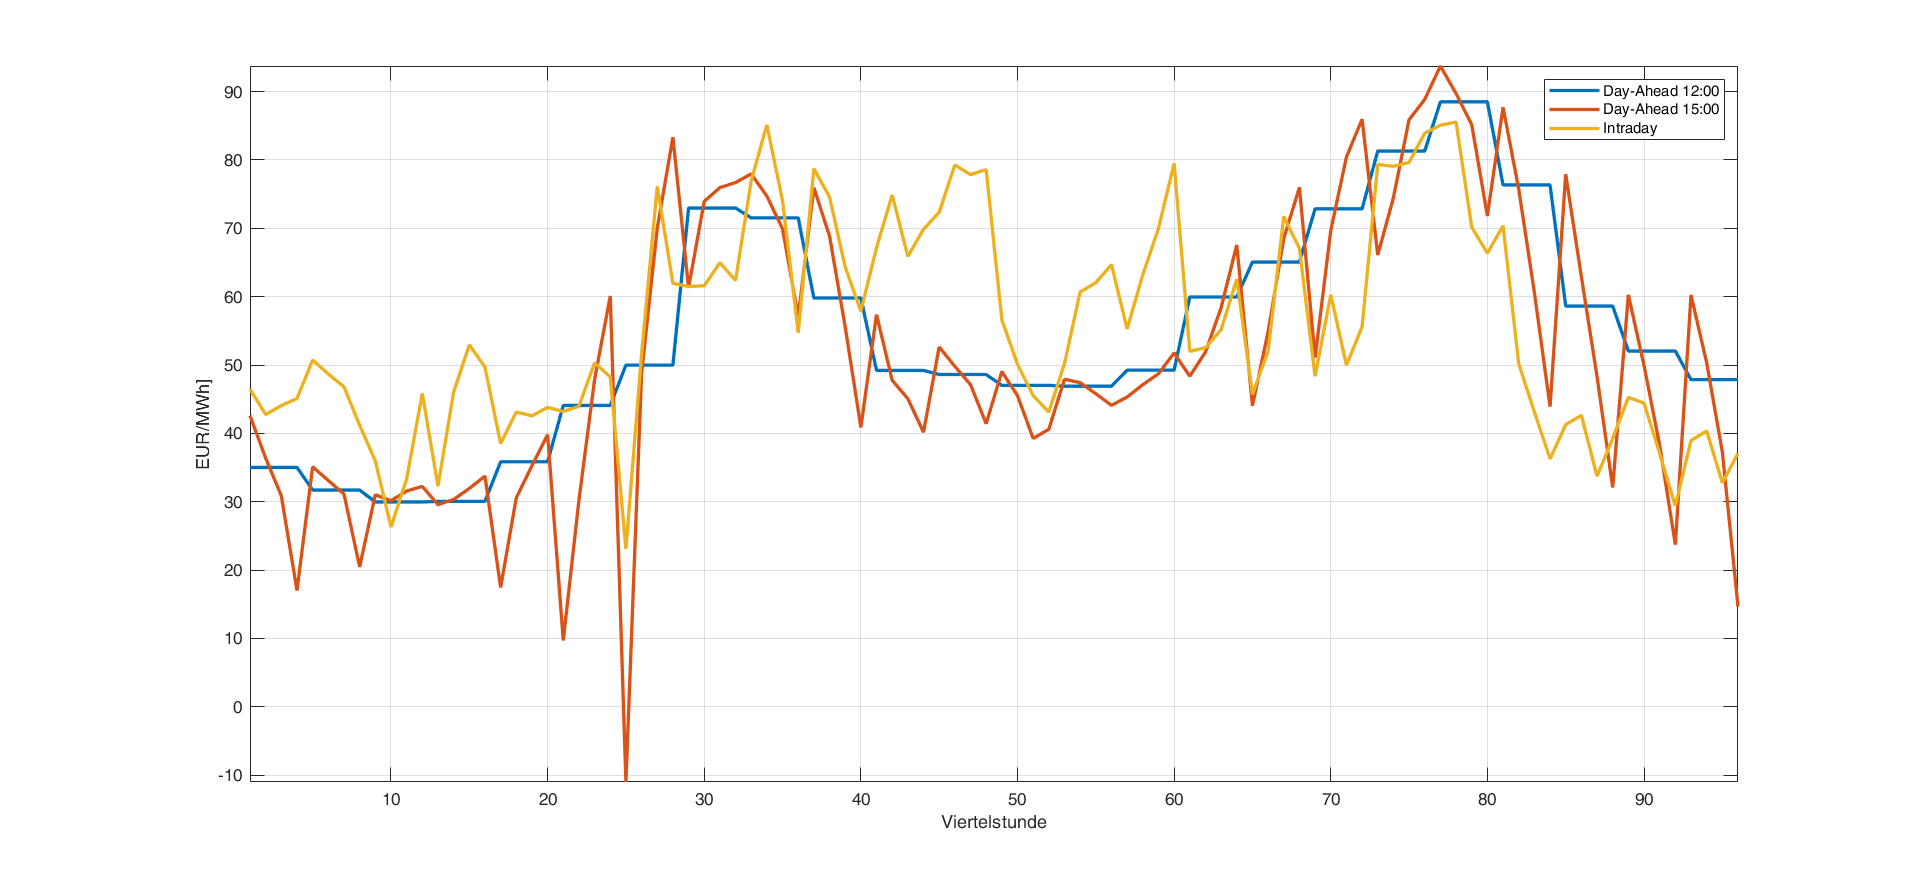

figure(gr.f(2))


gr.tlo= tiledlayout(3,2);
gr.tlo.TileSpacing="compact";
gr.tlo.Padding="none";
gr.t(1)=nexttile; plot(Price.AP1(day,:),'LineWidth',3);grid on; ylabel('Preis [EUR/MWh]'); ...
    hold on;yyaxis right;plot(Market1.level(day,:),'LineWidth',3); ylabel('Volumen [MWh]'); ...
    bar(Market1.action(day,:));legend(["PriceDA 12:00" "Level" "in/out"],'Location',"northeast")
    axis tight;
title("CF Marktstufe separat= "+num2str(floor(Market1.ValueTrade(day,:)))+" €")

gr.t(2)=nexttile(3); plot(Price.AP2(day,:),'LineWidth',2,'Marker','+');grid on;ylabel('Preis [EUR/MWh]');  ...
    hold on;yyaxis right;plot(Market2.level(day,:),'LineWidth',3);ylabel('Volumen [MWh]');   ...
    bar(Market2.action(day,:));legend(["PriceDA15:00" "Level" "in/out"],'Location',"northeast")
    axis tight;
title("CF Marktstufe separat = "+num2str(floor(Market2.CFday(day,1)))+" €")

gr.t(3)=nexttile(5); plot(Price.AP3(day,:),'LineWidth',2,'Marker','+');grid on; ylabel('Preis [EUR/MWh]'); ...
    hold on;yyaxis right;plot(Market3.level(day,:),'LineWidth',3);ylabel('Volumen [MWh]');  ...
    bar(Market3.action(day,:));legend(["PriceIDC" "Level" "in/out"],'Location',"northeast")
    axis tight;
title("CF Marktstufe separat = "+num2str(floor(Market3.CFday(day,1)))+" €")

gr.t(4)=nexttile(2);  bar(Market1.VolumeTrade(day,:));axis tight
title("CF der Zusatzgeschäfte = "+num2str(int64(Market1.ValueTrade(day,1)))+" €")

gr.t(5)=nexttile(4);  bar(Market2.VolumeChangeTrade(day,:));
title("CF der Zusatzgeschäfte = "+num2str(int64(Market2.ValueChangeTrade(day,1)))+...
    " €. Summe: "+num2str(int64(Market1.ValueTrade(day,1)+...
    Market2.ValueChangeTrade(day,1)))+" €")
    axis tight

gr.t(6)=nexttile(6);  bar(Market3.VolumeChangeTrade(day,:));axis tight
title("CF der Zusatzgeschäfte = "+num2str(int64(Market3.ValueChangeTrade(day,1)))+...
    " €. Summe: "+num2str(int64(Market1.ValueTrade(day,1)+...
    Market2.ValueChangeTrade(day,1)+Market3.ValueChangeTrade(day,1)))+" €")
    axis tight
linkaxes(gr.t,'x')

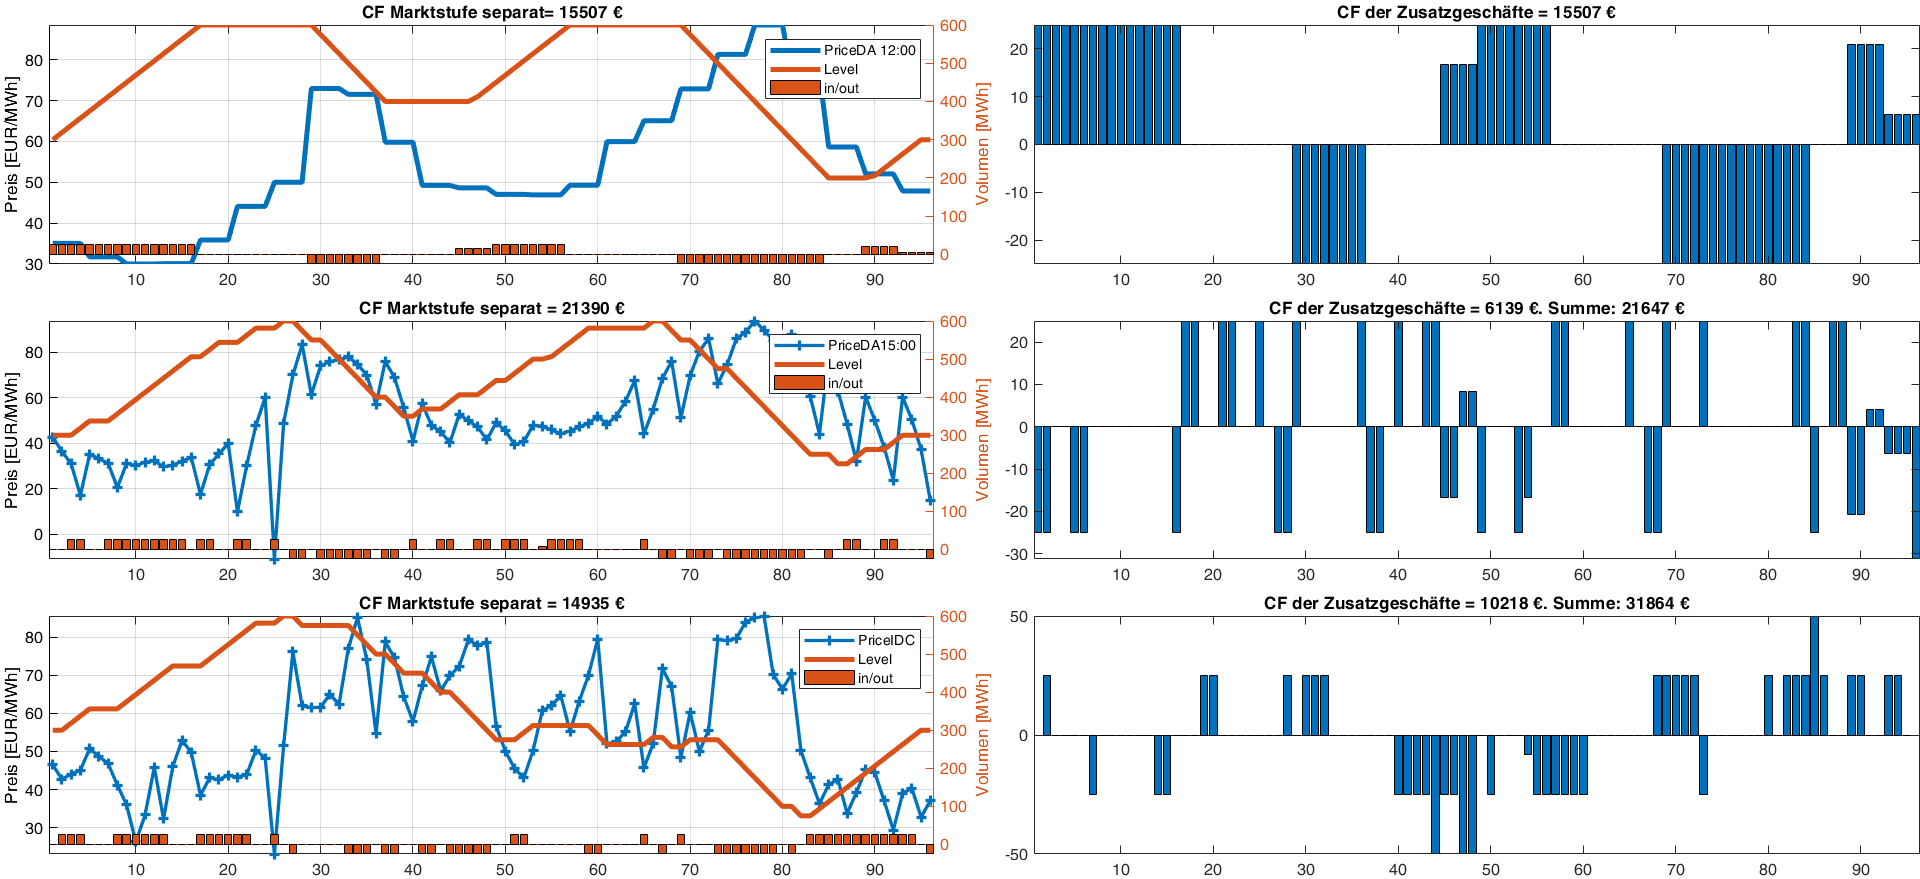


resDay = table();

resDay{[1 4 9],:}=round([Price.AP1(day,:);Price.AP2(day,:);Price.AP3(day,:)],2);
resDay{[2 6 11],:}=round([Market1.action(day,:);Market2.action(day,:);Market3.action(day,:)],2);
resDay{[6 10],:}=round([Market3.VolumeChangeTrade(day,:);Market3.VolumeChangeTrade(day,:)],2);

### kumuliertes Gesamtergebnis

Betrachtung der Ausgabe der Werte aus beiden Marktstufen pro Handelstag

figure(gr.f(2))
bar([Market1.ValueTrade Market2.ValueChangeTrade Market3.ValueChangeTrade],'stacked')
legend('1 Marktstufe','Zusatzerlös 2. Marktstufe','Zusatzerlös 3. Marktstufe')
title('Erlöse aus erster und zweiter Marktstufe je Handelstag')
xlabel('Handelstag');ylabel('Cash-Flow [€]')
axis tight;grid on

Betrachtung der Ausgabe der Wertentwicklung der einzelnen Strategien im Zeitablauf

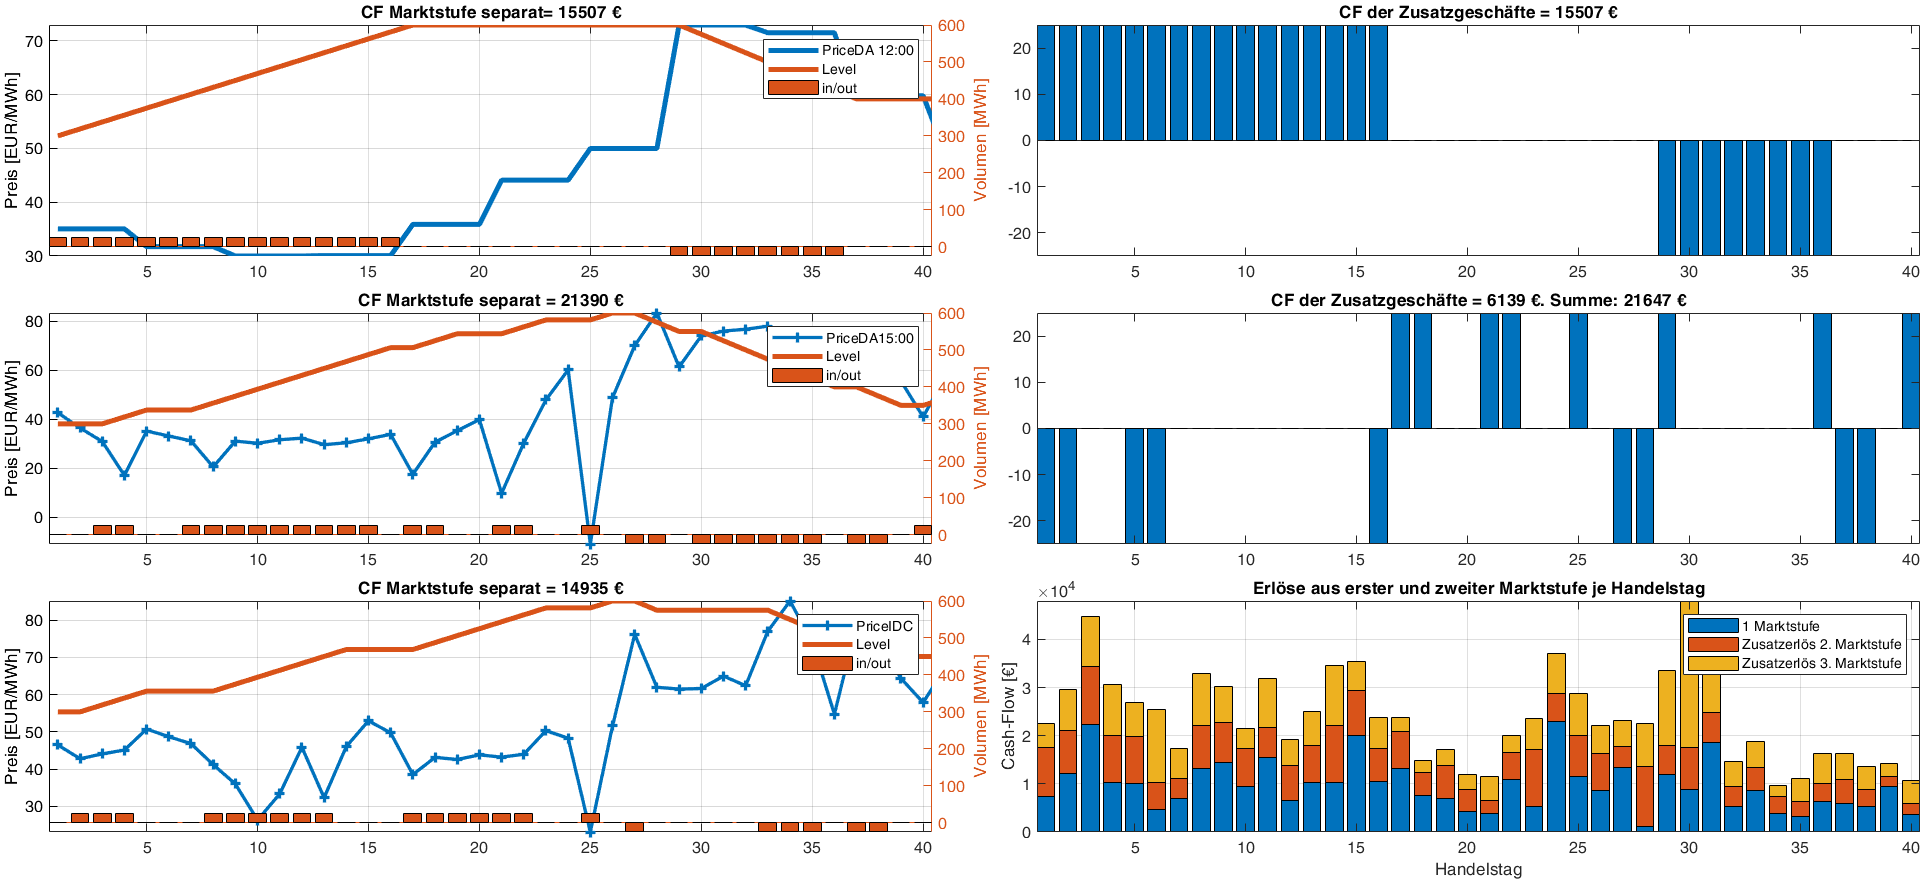

figure(gr.f(3))
plot([cumsum(Market1.ValueTrade)  cumsum(Market2.CFday) cumsum(Market3.CFday) cumsum(Market1.ValueTrade+Market2.ValueChangeTrade+Market3.ValueChangeTrade)])
legend('1. Marktstufe separat','2. Marktstufe separat','3. Marktstufe separat','Rolling')
title('Erlöse je Marktstrategie im Zeitablauf')

xlabel('Handelstag');ylabel('Cash-Flow [€]')
axis tight

Betrachtung des kumulierten Ertrages je Vermarktungsstrategie

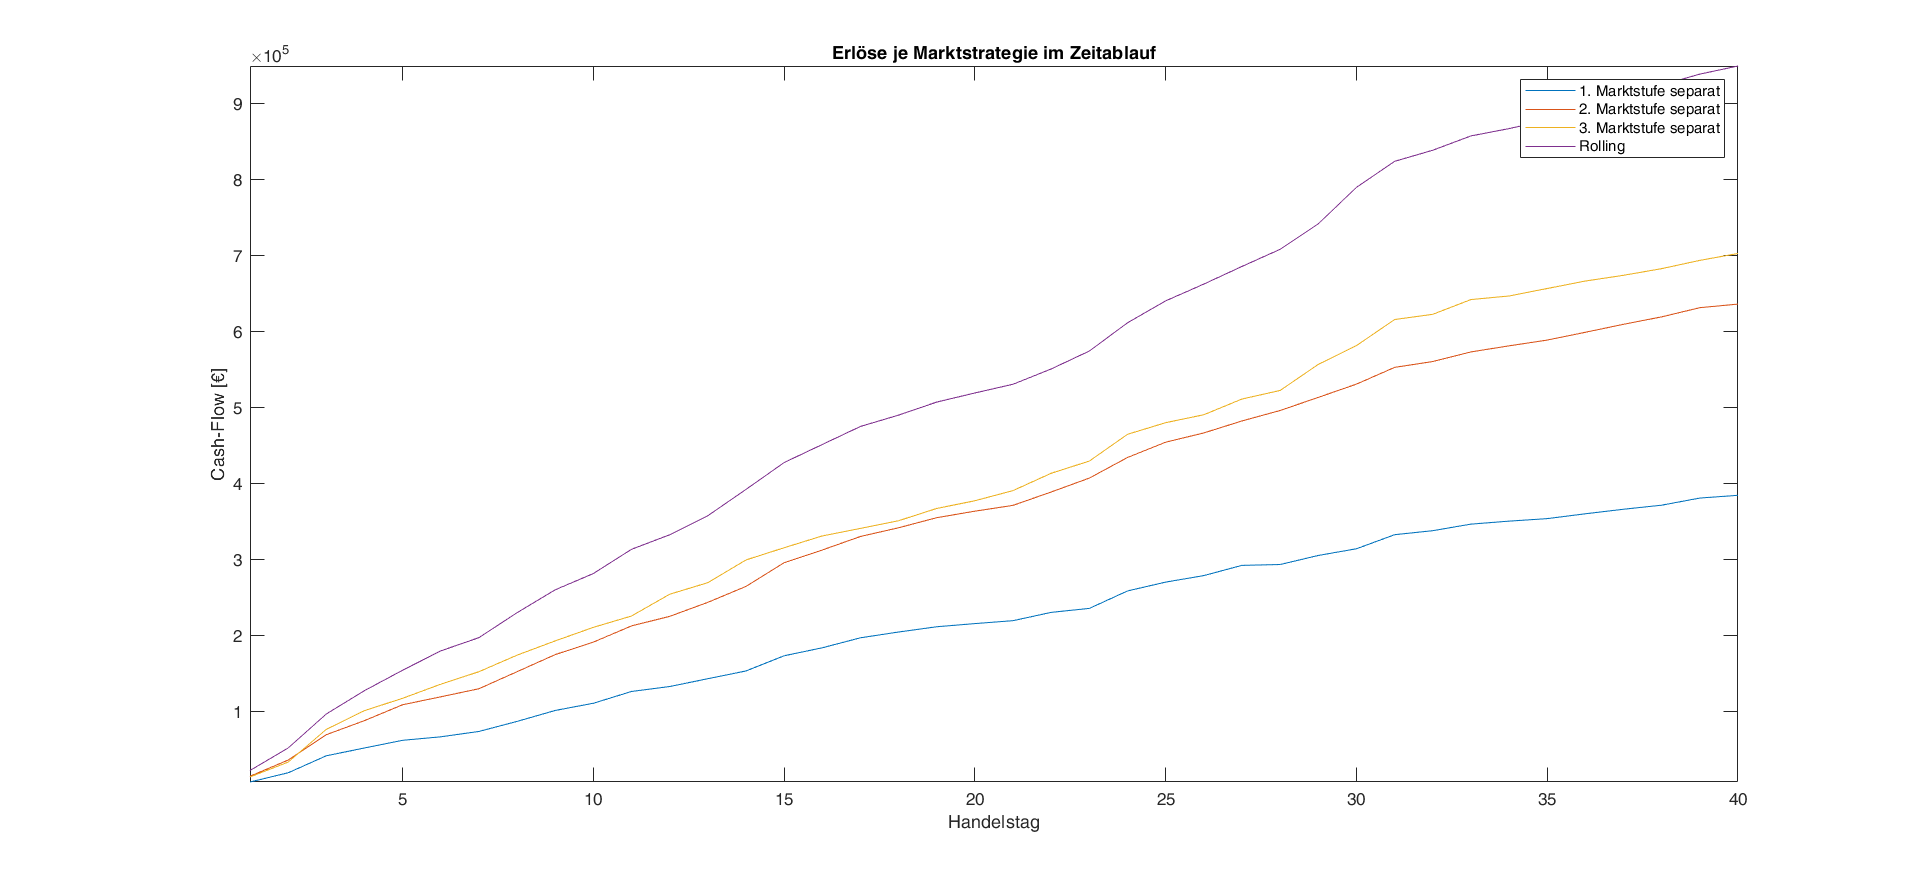

figure(gr.f(4))
gr.b=bar([sum(Market1.ValueTrade)  sum(Market2.CFday) sum(Market3.CFday) sum(Market1.ValueTrade+Market2.ValueChangeTrade+Market3.ValueChangeTrade)]);
title('Erlöse je Marktstrategie')
xlabel('Strategie');ylabel('Cash-Flow [€]')

gr.ax=gca; gr.ax.XTickLabel=["1. Marktstufe" "2. Marktstufe" "3. Marktstufe" "Rolling"] ;
grid on
gr.xtips2 = gr.b.XEndPoints;
gr.ytips2 = gr.b.YEndPoints;
labels2 = string(floor(gr.b.YData));
text(gr.xtips2,gr.ytips2,labels2,'HorizontalAlignment','center',...
    'VerticalAlignment','bottom')
axis tight
clear xtips2 ytips2 labels2

**Check ob Optimierung durchgelaufen ist **

1 bedeutet keine Auffälligkeiten

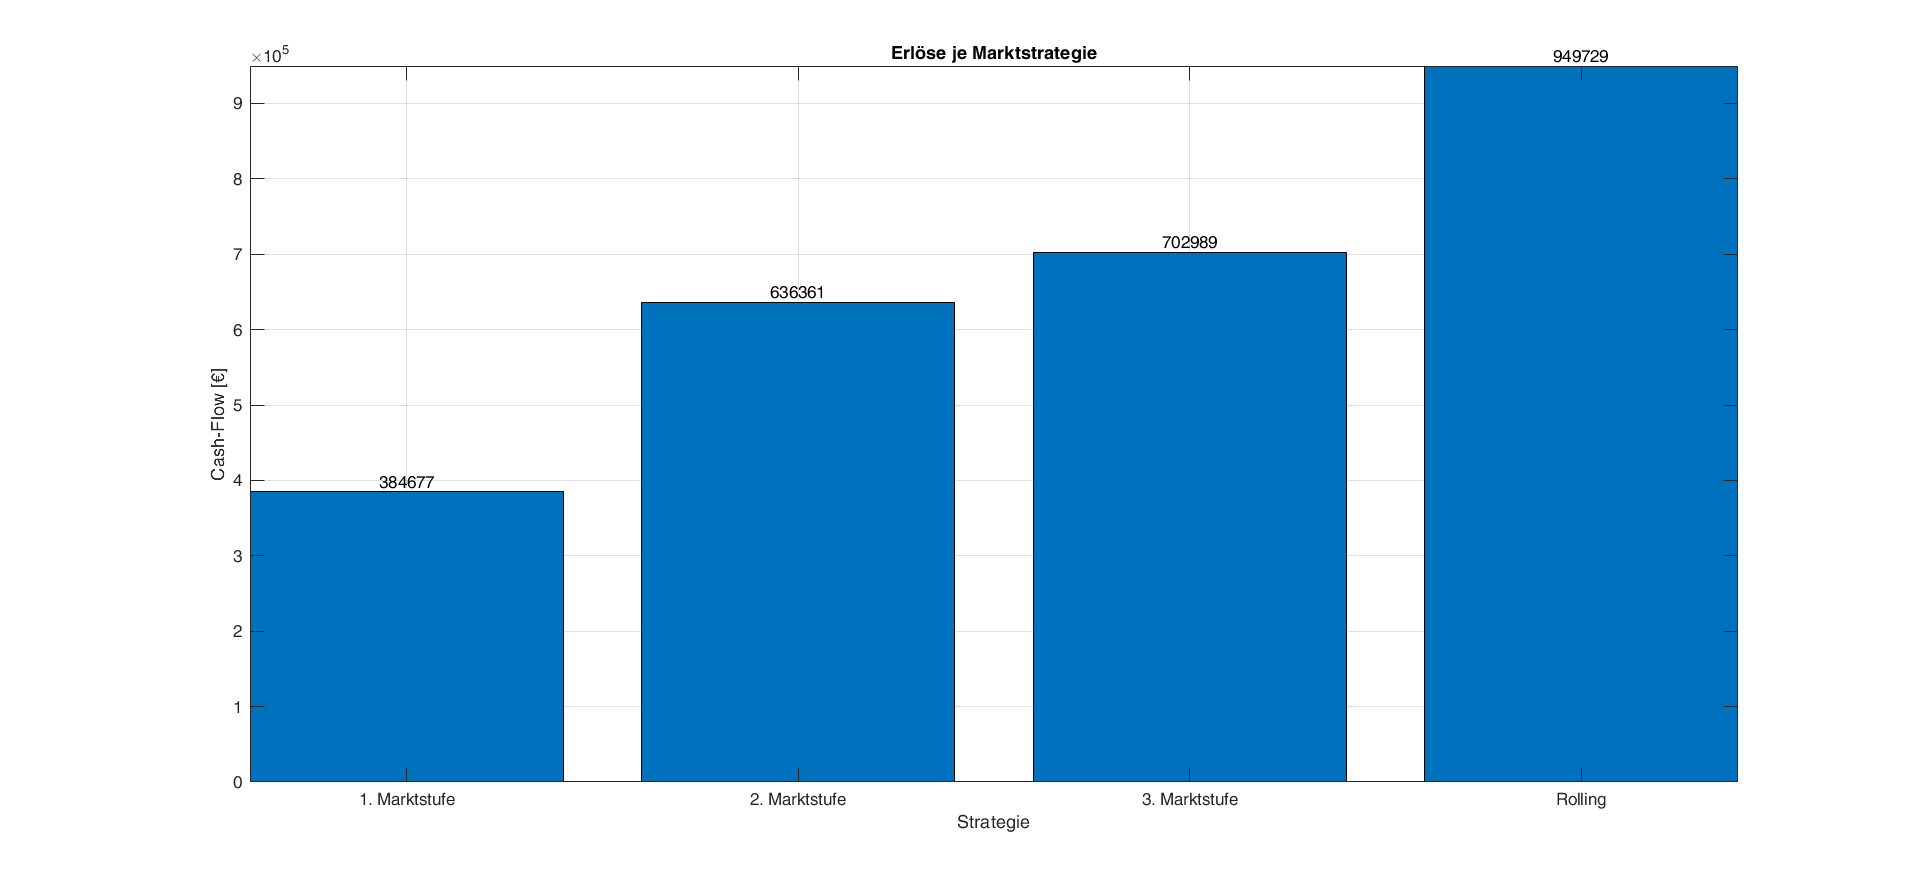

for i=1:3;check(i)=eval(["sum(OPT"+string(i)+".exitflag(:))"])/days;end;check

Zeitreihen werden in Excel zurückgeliefert

STOR.Tout = days;
outexcel =table();
outexcel.Datum =Price.Datum(1:STOR.Tout*96);
outexcel.Jahr =outexcel.Datum.Year;

check =      1     1     1


outexcel.PriceDA = reshape(Price.AP1(1:STOR.Tout,:)',[],1);
outexcel.action =  reshape(Market1.action(1:STOR.Tout,:)',[],1); 
outexcel.level =  reshape(Market1.level(1:STOR.Tout,:)',[],1); 
outexcel.HGVol =  reshape(Market1.VolumeTrade(1:STOR.Tout,:)',[],1);
outexcel.PriceIDA = reshape(Price.AP2(1:STOR.Tout,:)',[],1);
outexcel.action2 =  reshape(Market2.action(1:STOR.Tout,:)',[],1); 
outexcel.level2 =  reshape(Market2.level(1:STOR.Tout,:)',[],1); 
outexcel.HGVol2 =  reshape(Market2.VolumeChangeTrade(1:STOR.Tout,:)',[],1);
outexcel.PriceIDC = reshape(Price.AP3(1:STOR.Tout,:)',[],1);
outexcel.action3 =  reshape(Market3.action(1:STOR.Tout,:)',[],1); 
outexcel.level3 =  reshape(Market3.level(1:STOR.Tout,:)',[],1); 
outexcel.HGVol3 =  reshape(Market3.VolumeChangeTrade(1:STOR.Tout,:)',[],1);
writetable(outexcel,"IR.xlsx",'Sheet',1,'Range',"A115")

Unable to write to file 'C:\Users\VassilyAliseyko\Documents\ewi\flex\IR.xlsx'.  You may not
have write permissions or the file may be open by another application.

## Aufgabe:

- Betrachten Sie die zweite Abbildung. Versuchen Sie die linke Spalte der Abbildungen (separate Optimierung) zu plausibilsieren. Versuchen Sie darauf basierend die vorgenommene Anpassung der Handelsgeschäfte (rechte Seite Balkengraphiken) nachzuvollziehn. Hinweis: Sie können auf der X-Achse einer Abbildung zoomen; alle anderen Abbildungen passen sich automatisch an. Sie sollten die Graphiken in ihrer Entstehung erklären können (prüfungsrelevant!). Alternativ können Sie in Excel für eine bessere Auflösung wechseln.

- Wählen Sie andere Handelstage aus und machen sich mit den Ergebnissen vertraut. Setzen Sie den Regler für day auf 3. Analysieren Sie die Aktivitäten in diesem Handelstag im Day-Ahead  und überlegen ob dies wirtschaftlich sinnvoll ist (inbesondere zu Beginn des Handelstages). Überlegen Sie wie Sie in der Zielfunktion einen Term einbauen können, wodurch eine Aktivität im Speicher mit einem zu kleinen Spread vermieden wird. Setzen Sie dies um und schauen Sie das Resultat am Tag 3 in einer veränderten Aktivität an.

- Betrachten Sie die Abbildungen 3 - 4 und erfassen deren Bedeutung.

- Was passiert wenn Sie die Viertelstundenrestriktion Z. 36-37 auskommentieren?

- Betrachten Sie die Auswirkungen in Form des resultierenden Cash-Flows. Warum ist der Rolling-Wert hier deutlich höher?

- Vergleichen Sie den Wert einer Batterie (Wirkungsgrad 90% mit dem Wirkungsgrad eines alten Pumpspeichers 70%). Hinweis: den Wirkungsgrad können Sie in Zeile 19 einstellen. Was bedeutet dies für die zukünftige Wettbewerbspositionierung von Pumpspeichern bei zunehmender Elektromobilität?

- Worauf sind die Preisgradienten in den nachfolgenden Marktstufen 2 und 3 zurückzuführen. Was erwarten Sie für die zukünftige Entwicklung der Gradienten im Rahmen der Dekarbonisierung und zunehmenden Sektorenkopplung?

- Versuchen Sie zu eruieren, welcher Werteffekt  die viertelstündlichen Preisgradienten auf den Speicher haben. Welcher Wert würde verbleiben, wenn mittelfristig die Viertelstunden-Gradienten verschwinden würden (jede der 4 Viertelstunden erhält den gleichen mittleren Preis aller 4 Viertelstunden). Versuchen Sie Ihre Annahme zu überprüfen, indem Sie die Preise entsprechend manipulierenund die Bewertung erneut starten.

- Versuchen Sie herauszufinden, welcher zusätzlicher Wert verbunden ist mit:

- Umrüstung auf einen Speicher dessen Turbinierleistung das Doppelte der Pumpleistung beträgt.

- Einer Erhöhung des Speichervolumen um 10%

- einer Erhöhung von Pump- und turbinierleistung um 10%

            Warum lohnt es sich mehr die Leistung als das Volumen anzupassen?